% Plot graphs
Plot = false;

% Determine where your m-file's folder is
folder = fileparts(which("opt_problem.mlx"));
% Add that folder plus all subfolders to the path
addpath(genpath(folder));

#### GFDM parameters.

gfdm = struct;
gfdm.K = 16; % Subcarriers
gfdm.M = 8; % Subsymbols

gfdm.CP = 0; % CP length

SEM = "802.11ac";
Channel = 80; % Channel bandwidth (MHz)
B_low = Channel; % transmission bandwidth
B_up = 2*Channel;

gfdm = GFDM_init(gfdm);

D = gfdm.D;

Normalized frequency $f$ and normalized frequency interval $\Delta f$

delta_f = 0.001;     % Normalized frequency: f = F/Fs = F/2B = F*Ts
f_range_end = 0.5;   % rc filter limit

% f_range_end should be divisible by delta_f
if mod(f_range_end,f_range_end)
    msg = 'normalized frequency sampling interval delta_f can not equally spaces f_range';
    error(msg);
end

f_range = [0 f_range_end];
f = -f_range(2):delta_f:f_range(2);

Interpolation filter $P(f)$

P = rc_filter(delta_f, f_range, 0.1);

All combinations of $K_{\textrm{on}}$ and $M_{\textrm{on}}$ with decreasing order: $N$

The number of element used $N_{\textrm{sort}} \left(n\right)$ is the result of using $K_{\textrm{on}}$ = $\textrm{sort}\_\textrm{idx}\_K\left(n\right)$ and $M_{\textrm{on}}$ = $\textrm{sort}\_\textrm{idx}\_M\left(n\right)$.

[N_sort, sort_idx_K, sort_idx_M] = sort_N(gfdm);

#### Find the maximum used resource $N$ and its corresponding $K_{\textrm{on}}$ and $M_{\textrm{on}}$.

% Loop used resources
N_counter = 1;
N_start = tic;
for n = 31:D % Cut down the top utilizations to save time
    N = N_sort(n);
    gfdm.K_on = sort_idx_K(n); gfdm.M_on = sort_idx_M(n);
    fprintf("%d. K_on = %d M_on = %d N = %d \n", N_counter, gfdm.K_on, gfdm.M_on, N);
    fprintf("Utilize rate: %f \n", N/D);
    
    S = Dottorro(gfdm, Channel, Channel, P, f_range, delta_f);
    
    if ~isnan(S)
        % Break when feasible
        break;
    end
    
    N_counter = N_counter + 1;
end

fprintf('===============================\n');
fprintf("K_on = %d M_on = %d N = %d \n", gfdm.K_on, gfdm.M_on, N);
fprintf("Utilized rate: %f \n", N/D);
fprintf('Max utilization time: %s\n', duration([0, 0, toc(N_start)]));
fprintf('===============================\n');

#### Bisection method to find the max transmission bandwidth $B$.

% Bisection stop criteria
B_criteria = 0.1;
B_diff = B_criteria;
B_mid = B_up;
while B_diff >= B_criteria

#### Dottorro iterative algorithm & optimization problem


$$\mathbf{S}=\mathbf{g}\mathbf{g}^H$$


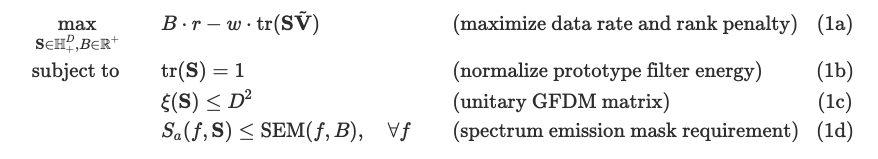

    S = Dottorro(gfdm, B_mid, Channel, P, f_range, delta_f);
    
    if isnan(S)
        % Bisection update if infeasible
        B_up = B_mid;
    else
        S_solved = S;
        
        % Bisection update if feasible
        B_low = B_mid;
        B = B_mid;
        
        if Plot == 1
            S_a_S = PSD_S(gfdm, S, psd_temp, f_range, delta_f);
            plot_PSD((P.^2) .* S_a_S, mask_linear, f_range);
        end
        
    end
    
    B_diff = B_up - B_low;
    % Midpoint
    B_mid = (B_up + B_low)/2;
end

 
switch SEM
    case "802.11ac"
        mask_dB = SEM_ac(delta_f, f_range, B, Channel);
    case "802.11b"
        mask_dB = SEM_b(delta_f, f_range, B, Channel);
end
mask_linear = db2pow(mask_dB);
psd_temp = zeros(size(P));
% g = S2g(S); G = g2chaG(g, gfdm.K, gfdm.M);
% S_a = PSD_G(gfdm, G, f_range, delta_f);
S_a_S = PSD_S(gfdm, S_solved, psd_temp, f_range, delta_f);
plot_PSD((P.^2) .* S_a_S, mask_linear, f_range);
title(['B=', num2str(B)]);
text(-0.2, -50, ['$K=$' num2str(gfdm.K) ', $M=$' num2str(gfdm.M)], 'interpreter','latex');
text(-0.2, -55, ['$K_{on}=$' num2str(gfdm.K_on) ', $M_{on}=$' num2str(gfdm.M_on)], 'interpreter','latex');